# Coordinate Frames and Rigid Body Motions

clear; clc; close all;

In this document, we will think about kinematics of orientations in 3D space, following the treatment in Murray, Li, Sastry. Additionally, we will adopt reference frame conventions similar to those used in Pinocchio, for smoother transitions to implementing on hardware. The reference frames considered will be:

- O: World Frame

- B: Local Frame (Body Frame)

- A: World Aligned Local Frame

The code below considers a rigid body, located at position (1,1,1), with roll and pitch angles of 45deg. The given frames are visualized:

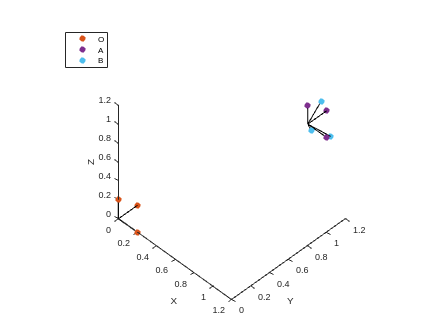

p = [1 1 1]';
roll_deg = 45;
pitch_deg = 45;

fh1 = figure();
plot_frame(fh1, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh1, p, eye(3), 'rot', 'A')
plot_frame(fh1, p, eul2rotm(deg2rad([roll_deg, pitch_deg, 0]), 'XYZ'), 'rot', 'B')

## Representing Orientation and Pose

There are several ways of representing orientations and poses of rigid bodies in 3D space. The translational component is straightforward to represent, composed of a vector $p \in \mathbb{R}^3$. The rotational component is accompanied by a choice; several representations (such as euler angles, or any 3-number parameterization) have singularities, while others (requiring 4 or more numbers) are singularity free. Singular representations work if orientations do not deviate far from an operating point, but singularity free represenations are much cleaner. Therefore, we will primarily consider singularity free representations, namely the rotation matrix, $R \in SO(3)$, and the quaterion $q \in S^3$. 

### Rotation Matrices

A rotation matrix encodes the orientation of a rigid body by locating the axes of the body frame ($B$) in the world frame ($O$). In general, take the matrix $R_{ab} \in SO(3)$ to be a rotation matrix expressing the orientation of frame $B$ in reference to the frame $A$.  

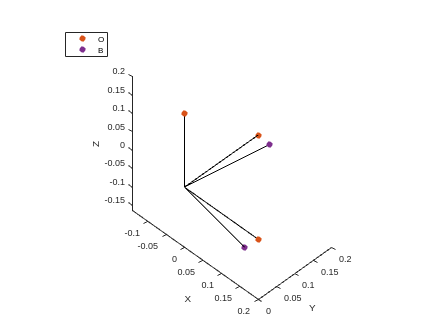

x = [1 1 1]'; x = x / norm(x);
y = [0.5 0.5 -1]'; y = y / norm(y);
z = cross(x, y);

R_ob = [x y z];
fh2 = figure();
plot_frame(fh2, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh2, [0,0,0]', R_ob, 'rot', 'B')

### Quaternions

Quaterions represent the orientation of a rigid body by a 4-tuple of numbers, which have unit magnitude.  The set of quaternions double-cover the space of rotations, as a quaternion and its negative represent the same orientation.

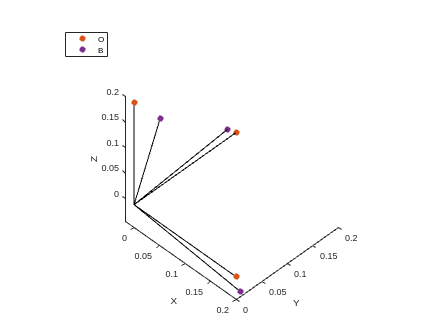

q = rand(1, 4); q = q / norm(q);
fh3 = figure();
plot_frame(fh3, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh3, [0,0,0]', q, 'quat', 'B')

## Coordinate Transformations

Consider a vector $v \in \mathbb{R}^3$ and a point $p \in \mathbb{R}^3$. These quantities can be expressed with respect to any coordinate frame. 

### Rotation Matrices

If a vector is expressed in a coordinate frame $B$, then the same vector can be expressed in coordinate frame $A$ by using the rotation matrix as a transformation:


$$v_a = R_{ab} v_b$$


Intitution for this can be gathered by considering unit vectors in the $B$ frame, and how these corrospond to columns of the rotation matrix. Multiple coordinate transforms can be chained together by continuing left multiplication:


$$v_a = R_{ab} R_{bc} v_c$$


### Exponential Coordinates

A rotation can also by expressed as rotation about an axis $\omega$ (unit vector) by an angle $\theta$ (according to the right hand rule). This can be encoded by


$$R(\omega, \theta) = e^{\hat{\omega} \theta}$$


Where $e^{(\cdot)}$ is the matrix exponential and $\hat{\omega} = \left[\matrix{0 & -\omega_3 & \omega_2 \cr \omega_3 & 0 & -\omega_1 \cr -\omega_2 & \omega_1 & 0} \right]$, such that $\hat{\omega} v = \omega \times v$. The result is precisely the rotation matrix corrosponding to the angle-axis rotation.

### Quaternions

Quaternions have a product operation; unit quaternions form a group under the multiplication operations. Additionally, they are represented easily as axis-angle: $q = (q_0, \vec{q})$ (in w,x,y,z format) corrosponds to $(\omega, \theta)$ angle axis representation by $q_0 = \cos(\theta / 2)$, $\vec{q} = \omega \sin(\theta / 2)$. 

% function [omega, theta] = quat2aa(q)
% theta = 2 * acos(q(1));
% if theta == 0
%     omega = zeros(3, 1);
% else
%     omega = q(2:4)' / sin(theta / 2);
% end
% end
% 
% function q = aa2quat(omega, theta)
% omega = omega / norm(omega);
% q = [cos(theta / 2) omega' * sin(theta / 2)];
% end
% 
% function R = aa2rot(omega, theta)
% o = omega / norm(omega);
% R = expm([0 -o(3) o(2); o(3) 0 -o(1); -o(2) o(1) 0] * theta);
% end
% 
% function [omega, theta] = rot2aa(R)
% theta = acos((trace(R) - 1) / 2);
% if theta == 0
%     omega = zeros(3, 1);
% else
%     omega = [R(3, 2) - R(2, 3), R(1,3) - R(3,1), R(2,1) - R(1,2)]' / (2 * sin(theta));
% end
% end

Now, check to make sure each of these transformations works

% Random angle-axis
aa = angleaxis(rand(3, 1) - 0.5, rand() * 2 * pi - pi);

aaq = quat2aa(aa2quat(aa));
assert(norm(aa.theta - aaq.theta) + norm(aa.omega - aaq.omega) < 1e-3 | ...
    norm(aa.theta + aaq.theta) + norm(aa.omega + aaq.omega) < 1e-3)

R = aa2rot(aa);
aaR = rot2aa(R);
assert(norm(aa.theta - aaR.theta) + norm(aa.omega - aaR.omega) < 1e-3 | ...
    norm(aa.theta + aaR.theta) + norm(aa.omega + aaR.omega) < 1e-3)

[w, x, y, z] = parts(randrot()); q = [w, x, y, z];
qaa = aa2quat(quat2aa(q));
assert(norm(q - qaa) < 1e-4)

R = quat2rotm(randrot());
Raa = aa2rot(rot2aa(R));
assert(norm(R - Raa) < 1e-4);

disp("Asserts passed")

Asserts passed


### Chaining Coordinate Transforms

Consider a set of three coordinate frames, $O, A, B$. Assume that $R_{oa}, R_{ab}$ are known, i.e. frame $A$ is defined relative to $O$, and frame $B$ is defined relative to $A$. Then frame $B$ expressed in frame $O$ is defined: $R_{ob} = R_{oa} R_{ab}$. 

A similar result holds for quaterions; given $q_{oa}, q_{ab}$ we have $q_{ob} = q_{oa} \cdot q_{ab}$, with $(\cdot)$ being quaternion multiplication. Check this result:

[w, x, y, z] = parts(randrot()); q_oa = [w, x, y, z];
[w, x, y, z] = parts(randrot()); q_ab = [w, x, y, z];

R_oa = aa2rot(quat2aa(q_oa));
R_ab = aa2rot(quat2aa(q_ab));

q_ob = quat_mult(q_oa, q_ab);
R_ob = R_oa * R_ab;

R_ob_q = aa2rot(quat2aa(q_ob));
assert(norm(R_ob - R_ob_q) < 1e-4)
disp("Asserts passed")

Asserts passed


### Inverting Coordinate Transforms

Given two frames, $A, B$, and the transform between them, $R_{ab}$, the inverse transform, i.e. the position of the $A$ frame relative to the $B$ frame, is $R_{ba} = R_{ab}^{-1}$. For rotation matrix representations, this is simply the matrix inverse, and as rotation matrices are orthogonal, $R_{ab}^{-1} = R_{ab}^\top$. For unit quaternions, we define the quaternion inverse


$$q^{-1} = (q_0, -\vec{q})$$


where the vector component (xyz) of the quaternion has been negated. 

assert(norm(eye(3) - R_oa * R_oa') < 1e-4)
assert(norm(eye(3) - R_oa' * R_oa) < 1e-4)

assert(norm([1 0 0 0] - abs(quat_mult(q_ob, quat_inv(q_ob)))) < 1e-4)
assert(norm([1 0 0 0] - abs(quat_mult(quat_inv(q_ob), q_ob))) < 1e-4)
disp("Asserts passed")

Asserts passed


## Rigid Motion in $\mathbb{R}^3$

So far, we have primarily been concerned with changes in orientation. Rigid body motion can also undergo translation; pairing translations with rotations results in $SE(3) = \{(p, R) ~\vert~ p \in \mathbb{R}^3, ~ R \in SO(3)\}$. 

### Homogeneous Representation

One method for representing points and vectors under rigid transfromations is via homogenous representations, where we first append a $1$to the end of the point, $\bar{p} = (p, 1)$. Vectors, which are the difference of points, are then represented as $\bar{v} = (v, 0)$. Given two coordinate frames $A, B$ which are separated by a translation $p_{ab}$ and a rotation $R_{ab}$. The homogeneous transform, $g_{ab}$ is then representable by the matrix


$$\bar{g}_{ab} = \left[ \matrix{R_{ab} & p_{ab} \cr 0 & 1} \right] $$
 

Homogeneous transforms can be chained together by defining the taking the product of the matrices:


$$\bar{g}_{ac} = \bar{g}_{ab} \bar{g}_{bc} = \left[\matrix{R_{ab} R_{bc} & R_{ab} p_{bc} + p_ab \cr 0 & 1}\right]$$


% function g = Rp2g(R, p)
% g = [R p; zeros(3,1), 1];
% end
% 
% function [R, p] = g2Rp(g)
% R = g(1:3, 1:3);
% p = g(1:3, 4);
% end

### Twist Representation

Twist representation, similarly to exponential coordinates for orientation, use the matrix exponential to define a homogeneous transform. A twist is defined $\xi = (v, \omega) \in \mathbb{R}^6$, where $v \in \mathbb{R}^3$ represents translational displacement, and $\omega \in \mathbb{R}^3$ represents and axis, scaled by the magnitude of rotation about it. We define


$$\hat{\xi} = \left[\matrix{\hat{\omega} & v \cr 0 & 0} \right]$$


Such that


$$e^{\hat{\xi}\theta} = \left[ \matrix{e^{\hat{\omega} \theta} & (I - e^{\hat{\omega} \theta})(\omega \times v) + \omega \omega^\top v \theta \cr 0 & 1}\right]$$


Note that this corrosponds to a rotation by $(\omega, \theta)$ in angle-axis representation, and a translation which depends on each of $\omega, v, \theta$. 

### Screw Representation

The twist rotation will become useful when thinking about velocities, but for displacements, the screw is more intuitive to think about. A screw consists of an axis, $l=p + \alpha \omega$ (where $p$ is a point on the axis and $\omega$ is the direction of the axis), a pitch $h$, and a magnitude, $\theta$. A screw motion is defined as a rotation of $\theta$ around the axis, followed by a translation by amount $h\theta$ along the axis. Any twist can be written as a screw, and vice versa. The homogeneous transform defined by a screw is


$$g = \left[ \matrix{e^{\hat{\omega}\theta} & (I - e^{\hat{\omega}\theta})p + h\theta\omega \cr 0 & 1}\right]$$


Choosing $v = -\omega \times p + h \omega$, the twist $\xi = (v, \omega)$ combined with $\theta$ generates the same homogenous transform as the twist. 

p = rand(3, 1) - 0.5;
omega = rand(3, 1) - 0.5;
h = rand() - 0.5;
theta = rand() * 2 * pi - pi;
s = screw(p, omega, h, theta);

v = -cross(s.omega, s.p) + h * s.omega;
xi = twist(v, s.omega);
gs = s.g;
gxi = twist2g(xi, s.theta);
assert(norm(gs - gxi) < 1e-4);
disp("Asserts passed")

Asserts passed


# Rigid Body Velocities

Now that we have discussed the geometry of rigid body motion, it is time to consider the evolution of motion over time.

## Rotational Velocity

Consider a rigid body, with a body fixed frame $B$, whose origin is aligned with the world frame $O$, but is rotating. The position of a point on the body, $q_b$, is constant over time w.r.t. the $B$ frame, but evolves with respect to the $A$ frame according to:


$$q_a(t) = R_{ab}(t) q_b$$


And its velocity is


$$v_{q_a}(t) = \dot{R}_{ab}(t) q_b = \dot{R}_{ab}(t) R_{ab}^{-1}(t) R_{ab}(t) q_b $$


since $\dot{q}_b = 0$. The matrix $\dot{R}_{ab} R_{ab}^{-1}$ is skew symmetric. We can therefore define two matrices:


$$\hat{\omega}_{ab}^s \triangleq \dot{R}_{ab} R_{ab}^{-1} \quad \quad \hat{\omega}_{ab}^b \triangleq R_{ab}^{-1} \dot{R}_{ab}$$


deemed the spatial and body angular velocities, related by


$$\hat{\omega}_{ab}^b = R_{ab}^{-1} \hat{\omega}_{ab}^s R_{ab} \quad \quad \omega_{ab}^b = R_{ab}^{-1} \omega_{ab}^s
$$


Where the second relation relates the vector representations of $\omega$. These give compact representations of the velocity of a point in either the body or spatial frames:


$$v_{q_a}(t) = \omega_{ab}^s(t) \times q_a(t) \quad \quad v_{q_b}(t) = \omega_{ab}^b(t) \times q_b$$


## Rigid Body Velocity

As with the case of rotation, $\dot{g}_{ab}$ is not particularly useful, but both $\dot{g}_{ab} g_{ab}^{-1}$ and $g_{ab}^{-1} \dot{g}_{ab}$ have significance. We define $\hat{V}_{ab}^s = \dot{g}_{ab} g_{ab}^{-1} \in se(3)$ to be the spatial velocity, with $V_{ab}^s = \left[ \matrix{v_{ab}^s \cr \omega_{ab}^s} \right] = \left[ \matrix{-\dot{R}_{ab} R_{ab}^{-1}p_{ab} + \dot{p}_{ab} \cr (\dot{R}_{ab} R_{ab}^{-1}p_{ab} + \dot{p}_{ab} )^\check} \right]$corrospondingly defined. The velocity of a point is $v_{q_a}(t) = \omega_{ab}^s \times q_a + v_{ab}^s$. Note that $v_{ab}^s$ is not the velocity of the $B$ frame origin relative to the $A$ frame, but rather the velocity of a point on the rigid body which is traveling through the origin of the spatial frame at time $t$. A similar construction can be defined for the body velocity:


$$\hat{V}_{ab}^b = g_{ab}^{-1} \dot{g}_{ab} = \left[ \matrix{R_{ab}^{-1} \dot{R}_{ab} & R_{ab}^{-1} \dot{p}_{ab} \cr 0 & 0}\right] \quad \quad V_{ab}^b = \left[ \matrix{v_{ab}^b \cr \omega_{ab}^b} \right] = \left[ \matrix{R_{ab}^{-1} \dot{p}_{ab} \cr (R_{ab}^{-1} \dot{R}_{ab})^\check} \right]$$


$\hat{V}_{ab}^b$ takes a point in the body frame and returns a body velocity. The interpretation of body velocity is straightforward: $v_{ab}^b$ is the velocity of the origin of the body coordinate frame relative to the spatial frame, as viewed in the current body frame. $\omega_{ab}^b$ is the angular velocity of the coordinate frame, also as viewed in the current body frame. This is not the velocity of the body relative to the body frame, as this is zero. Finally, note that


$$\hat{V}_{ab}^s = g_{ab} \hat{V}_{ab}^b g_{ab}^{-1}$$


To transform a twist from one frame to another, we define the adjoint operator


$$V_{ab}^s = \left[ \matrix{R_{ab} & \hat{p}_{ab} R_{ab} \cr 0 & R_{ab} }\right] \left[ \matrix{v_{ab}^b \cr \omega_{ab}^b}\right] = Ad_g V_{ab}^b$$


This mapping is invertible, with $Ad_{g}^{-1} = Ad_{g^{-1}}$. The adjoint operator allows us to chain velocities between frames. Given frames $A, B, C$, we have


$$V_{ac}^s = V_{ab}^s + Ad_{g_{ab}} V_{bc}^s  \quad \quad V_{ac}^b = Ad_{g_{bc}^{-1}}V_{ab}^b + v_{bc}^b$$


And similarly, frames can be reversed: 


$$V_{ab}^b = -V_{ba}^s \quad \quad V_{ab}^b = -Ad_{g_{ba}} V_{ba}^b$$


Finally, lets consider an example, with a three link manipulator. The links have length $l_1, l_2, l_3$. The configuration space is three joints, $\theta = (\theta_1, \theta_2, \theta_3)$. There are four frames; $O, B_1, B_2, B_3$. In the zero position, all coordinate frames have the same orientation. $A_1$ is located $l_1$ units along the $z$ axis of $O$, and is rotated an angle $\theta_1$ around the $z$ axis. $A_2$ is located $l_2$ units along the $y$ axis of $A_1$, rotated along the $y$ axis. Finally, $A_3$ is located $l_3$ units along the $x$ axis of $A_2$, and rotates along the $x$ axis. 

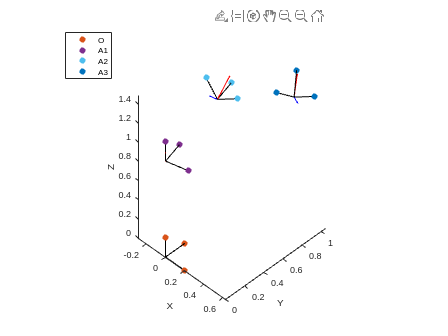

l1 = 1; l2 = 0.75; l3 = 0.75;
v1 = [0;0;l1]; v2 = [0;l2;0]; v3 = [l3;0;0];
w1 = [0;0; 1]; w2 = [0;1; 0]; w3 = [1; 0;0];

% forward kinematics
g_o = Rp2g(eye(3), zeros(3,1));
g_o1 = @(th1) Rp2g(aa2rot(angleaxis(w1, th1)), v1);
g_12 = @(th2) Rp2g(aa2rot(angleaxis(w2, th2)), v2);
g_23 = @(th3) Rp2g(aa2rot(angleaxis(w3, th3)), v3);

% First, visualize configurations
% th1 = 0; th2 = 0; th3 = 0;
th1 = 0.25; th2 = -0.5; th3 = 0.75;
g0_o1 = g_o1(th1); g0_12 = g_12(th2); g0_23 = g_23(th3); 
g0_o2 = g_mult(g0_o1, g0_12);
g0_o3 = g_mult(g0_o2, g0_23);

fh4 = figure();
plot_gframe(fh4, g_o, 'O')
plot_gframe(fh4, g0_o1, 'A1')
plot_gframe(fh4, g0_o2, 'A2')
plot_gframe(fh4, g0_o3, 'A3')

% Now, compute velocities (Body Velocities)
v01 = [0;0;0]; v12 = [0;0;0]; v23 = [0;0;0];
w01 = w1; w12 = w2; w23 = w3;
dth1 = 0.1; dth2 = 0.2; dth3 = -0.10;

% Unit twists
V_o1s_t = twist(v01, w01);
V_12s_t = twist(v12, w12);
V_23s_t = twist(v23, w23);

% Spatial Velocity functions
V_o1s = @(dot1) V_o1s_t.vec * dot1;
V_12s = @(dot2) V_12s_t.vec * dot2;
V_23s = @(dot3) V_23s_t.vec * dot3;

% Adjoints
Ad_go1 = Adg(g0_o1);
Ad_g12 = Adg(g0_12);
Ad_g23 = Adg(g0_23);

% Spatial Velocities
V0_o1s = V_o1s(dth1);
V0_12s = V_12s(dth2);
V0_23s = V_23s(dth3);

% Spatial Velocties relative to O
V0_o2s = V0_o1s + Ad_go1 * V0_12s;
V0_o3s = V0_o2s + Ad_g12 * V0_23s;

% Body Velocities
V0_o1b = Ad_go1 \ V0_o1s;
V0_12b = Ad_g12 \ V0_12s;
V0_23b = Ad_g23 \ V0_23s;

% Body Velocities relative to O
V0_o2b = Ad_g12 \ V0_o1b + V0_12b;
V0_o3b = Ad_g23 \ V0_o2b + V0_23b;

% Plot body velocities
plot_body_vel(fh4, V0_o1b, g0_o1)
plot_body_vel(fh4, V0_o2b, g0_o2)
plot_body_vel(fh4, V0_o3b, g0_o3)